
close all

## Collect Data

dt = 0.01; %sample time
input = scope{2}.Values

  timeseries

  Common Properties:
            Name: ''
            Time: [3001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [3001x1 double]
        DataInfo: 

output=scope{1}.Values

  timeseries

  Common Properties:
            Name: ''
            Time: [3001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [3001x1 double]
        DataInfo: 

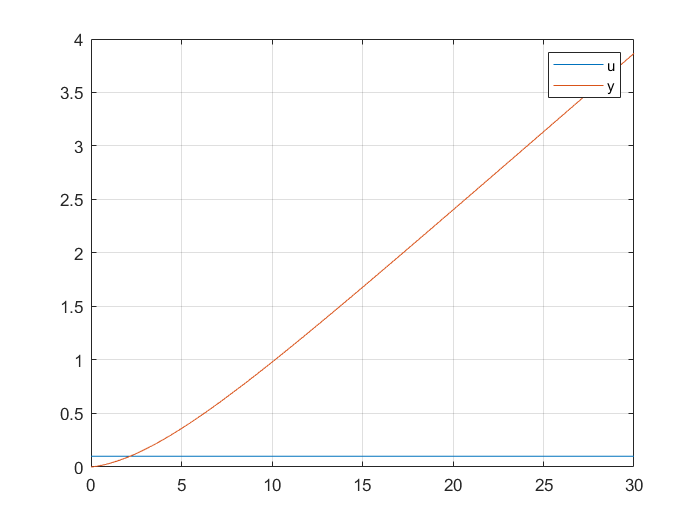

t=input.Time; %time

% Build the step input
u = input.Data;

% Simulate a step response
yreal =output.Data;

plot(t, [u, yreal])
grid on
legend(['u'; 'y']);

## Identify a transfer function model

% Fit data to a transfer function with unknown delay term
data = iddata(yreal, u, dt);
Gest = tfest(data, 2, 0, NaN)

Gest =
 
  From input "u1" to output "y1":
                           0.3494
  exp(-0.02*s) * --------------------------
                 s^2 + 0.2381 s + 4.578e-13
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 100%                     
FPE: 2.18e-13, MSE: 2.173e-13                    


## Validate the model

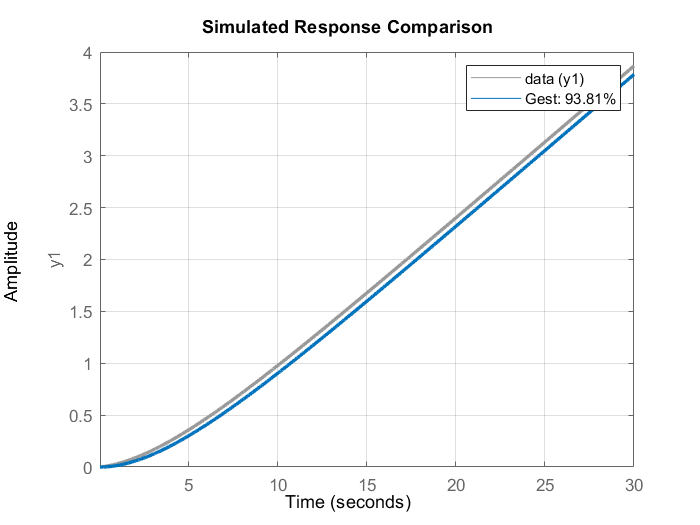

opt = compareOptions('InitialCondition', 'z');
compare(data, Gest, opt);
set(findall(gca, 'Type', 'Line'),'LineWidth',2);
grid on